% Define units
meter = 1;
millimeter = 10^(-3) * meter;
nanometer = 10^(-9) * meter;
%%%TASK: Sample the double slit pair over a region of total size 20
%%%millimeters
%Select the correct number of sample points so that the final region at 10m propagation is 64cm
%of course the number of samples will remain constant. To do this set l, N, and correctly call the Fraunhofer
%propagation
%Hint: N is a power of 2

%The slits make up such a small region of our sample initial condition so that we can get good resolution
%at the propagated plane.

%The scale factor s for N samples, over a region of width 2l, at a plane L away is s = [N * lambda * L / (2l)^2]

N = %Fill in
l = %Fill in

% Generate N equally spaced samples along the initial conditions
boundary_coordinates = linspace(-l, l, N);


% Sample the double slit function at those points
boundary_amplitude_samples = double_slit_pair(boundary_coordinates);
size(boundary_amplitude_samples)% Plot the double slit intensity, using a plotting function

ans =      1   256


plot_intensity_1d(boundary_coordinates, boundary_amplitude_samples, 'Double Slit Pair');

% Define the propagation distance and wavelength
L = 10 * meter;
lambda = 500 * nanometer;

% Compute the Fraunhofer propagation
[coordinates_prime, A_prime] = %Fill in, call Fraunhofer propagation

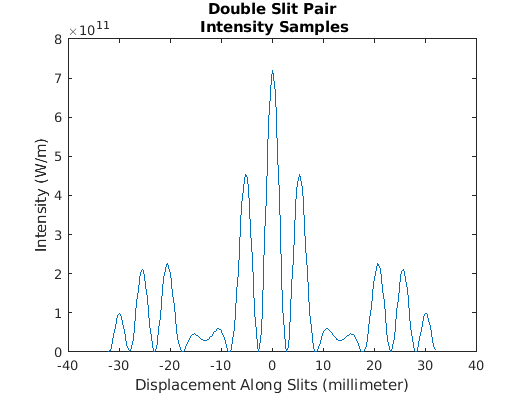

plot_intensity_1d_line(coordinates_prime, A_prime, "Double Slit Pair")

% Import an existing diffraction result and calculate its intensity
loaded_data = load('amplitudes_correct_double_slit_pair.mat'); % Load .mat file
intensity_prime = 1/2 * abs(loaded_data.A_prime).^2; % Calculate intensity

% Import coordinates
loaded_coords = load('coordinates_correct_double_slit_pair.mat'); % Load .mat file
coordinates_convolve = loaded_coords.coordinates_prime; % Extract coordinates

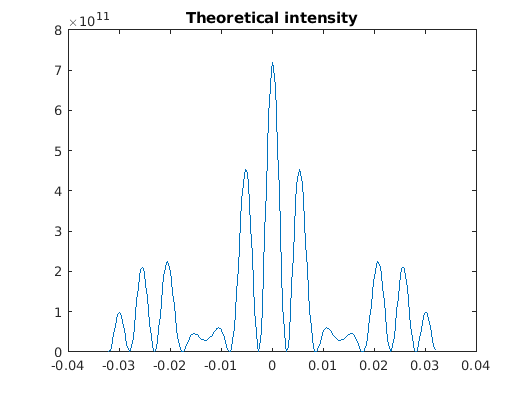


% Plot the intensity
plot(coordinates_convolve, intensity_prime);
title('Theoretical intensity');

bc = boxcar(coordinates_prime, 10 * millimeter);

%%%Task use the numpy.convolve function to calculate the true convolution of the 10 millimeter boxcar
%and the provided intensity. Then run the code to do a calculation of the circular convolution.
%The shape argument of conv is crucial, you want to pick it so that the number of samples remains N
%not more not less

%%%Task answer the following questions
%What differences do you notice between the results of the functions circular_convolve, and numpy.convolve? 
%Where are differences most prominent?

% Calculate the convolution
intensity_measured = %Fill in

intensity_circular_convolved = circular_convolve(intensity_prime, bc)

intensity_circular_convolved = 	1.0e+13 *

    0.1767    0.1827    0.1941    0.2099    0.2285    0.2483    0.2675    0.2846    0.2982    0.3077    0.3126    0.3132    0.3103    0.3049    0.2984    0.2923    0.2877    0.2859    0.2876    0.2930    0.3021    0.3143    0.3290    0.3451    0.3615    0.3774    0.3919    0.4044    0.4146    0.4227    0.4287    0.4330    0.4361    0.4383    0.4400    0.4412    0.4418    0.4416    0.4402    0.4370    0.4317    0.4241    0.4138    0.4012    0.3865    0.3706    0.3540    0.3380    0.3232    0.3107


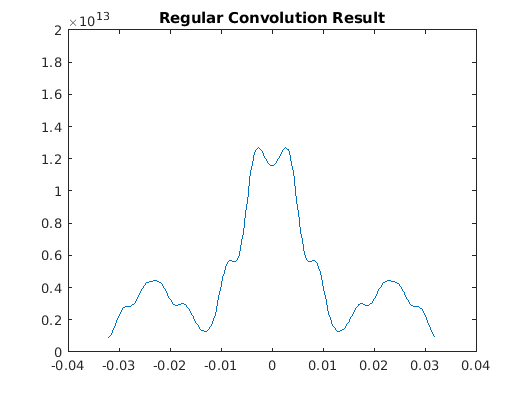

% Plot the regular convolution result
figure; % Create a new figure window
plot(coordinates_convolve, intensity_measured);
title('Regular Convolution Result');

% Set y-axis limits
ylim([0, 2 * 10^13]);

% Save the plot as a PNG file with high resolution
saveas(gcf, 'regular_convolve_result.png');

% Plot the circular convolution result
figure; % Create a new figure window
plot(coordinates_convolve, intensity_circular_convolved);
title('Circular Convolution Result');

% Set y-axis limits
ylim([0, 2 * 10^13]);

% Save the plot as a PNG file with high resolution
saveas(gcf, 'circular_convolve_result.png');